file_path1 = 'C:\Users\gajapathy.s\Desktop\gps\walkingRTK.bag';

file_path2 = 'C:\Users\gajapathy.s\Desktop\gps\gps_occ_walking.bag';

 alt(file_path1)

a1 =    27.8390   27.3230   26.9090   26.5120   26.6580   26.6470   26.4700   26.5810   26.7460   26.9150   26.5860   26.2360   26.4500   26.1430   26.0260   25.8720   25.7470   25.6260   25.1780   25.0550   24.6520   24.6110   24.6400   24.6980   24.4730   24.2370   24.1270   24.0260   23.9190   23.7990   23.7210   23.5840   23.5100   23.4320   23.5040   23.5850   23.4750   23.4130   23.3550   23.2320   23.0490   22.9470   22.8190   22.8820   22.9020   22.8420   22.6620   22.5740   22.4800   22.3050


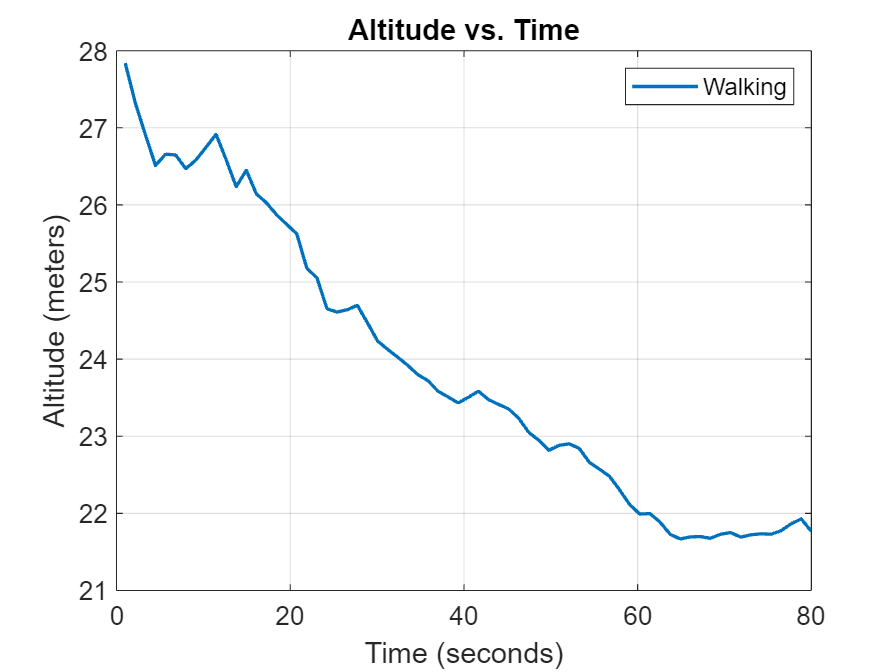

 hold off

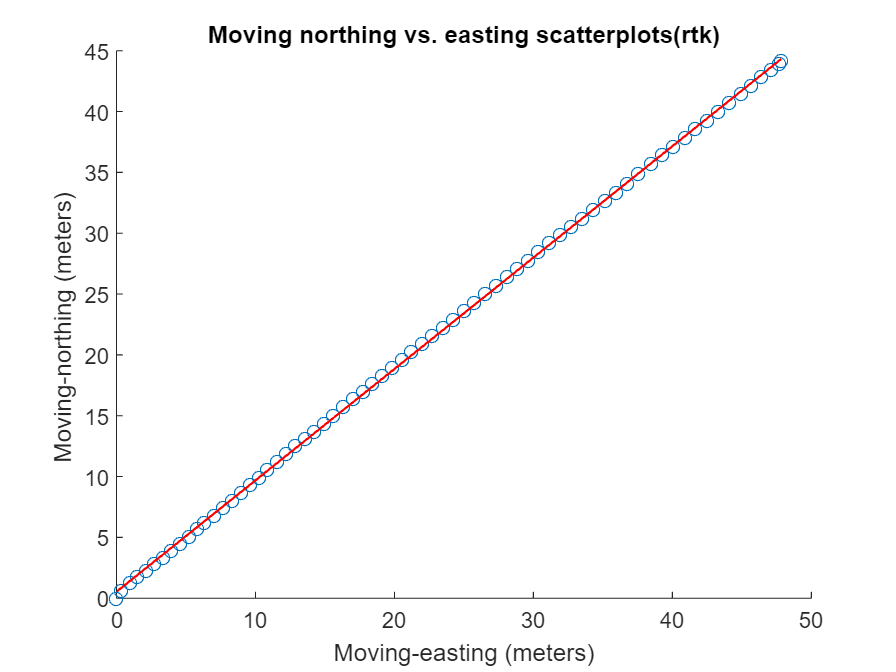


 [lat,long,Alt,UtmE,UtmN,delta_time,UE,UN]= extract_bag(file_path1);
 scatterplot(UN,UE);
 ur=UN;
 or= [UN; UE];
   
 p = polyfit(UN, UE, 1);

    y_fit = polyval(p, UN);
ir= [UN;y_fit];


    hold on;
    plot(UN, y_fit, 'r-', 'LineWidth', 1, 'DisplayName', 'Line of Best Fit');
    hold off;



xlabel('Moving-easting (meters)');
ylabel('Moving-northing (meters) ');
title('Moving northing vs. easting scatterplots(rtk)');
 % legend('Occluded walking ','Open walking')
hold off


 [lat,long,Alt,UtmE,UtmN,delta_time,UE,UN]= ex_bag(file_path2);


scatterplot(UN,UE)
ug=UN

ug =          0         0    0.1884    1.0969    1.9987    2.9072    4.0008    5.0876    6.1745    7.2680    8.3582    9.4451   10.3502   12.0125   13.4863   14.9635   16.4474   16.9757   17.4972   18.2038   19.1022   20.1890   21.2759   22.1742   23.2543   24.1527   25.0511   26.1346   27.0364   27.9348   28.8298   29.7316   30.6300   31.5317   32.4301   33.3252   34.2202   35.1220   36.0204   36.9154   37.8138   38.7122   39.6106   40.7008   41.7843   42.6827   43.7661   44.8496   45.9331   47.2050


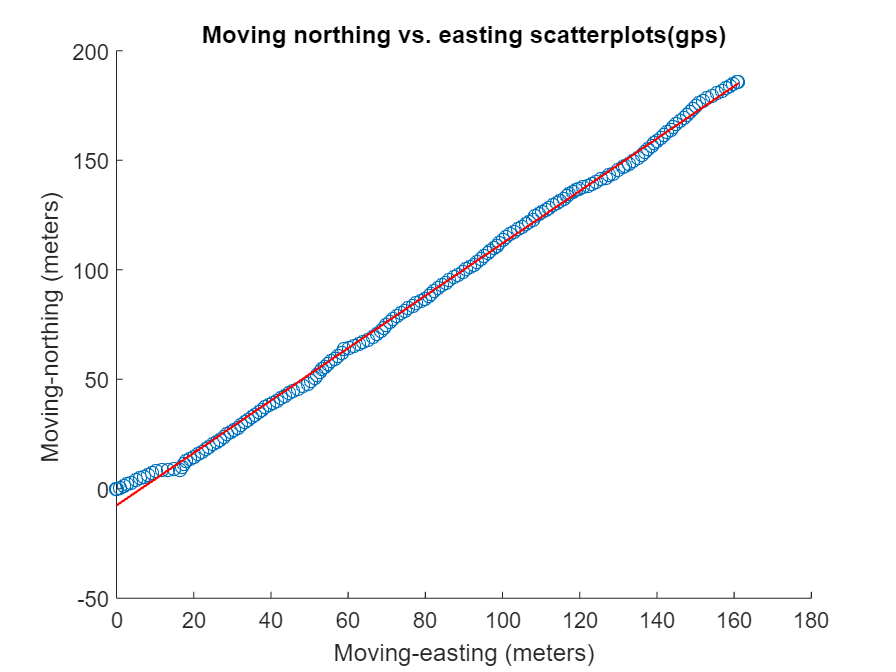

 og= [UN; UE];
   
 p = polyfit(UN, UE, 1);

    y_fit = polyval(p, UN);
ig= [UN;y_fit];


     hold on;
    plot(UN, y_fit, 'r-', 'LineWidth', 1, 'DisplayName', 'Line of Best Fit');
    hold off;


xlabel('Moving-easting (meters)');
ylabel('Moving-northing (meters) ');
title('Moving northing vs. easting scatterplots(gps)');
 % legend('Occluded walking ','Open walking')
hold off



error(ir,or,ur,'r',6)

Quantitative_error = 0.1839

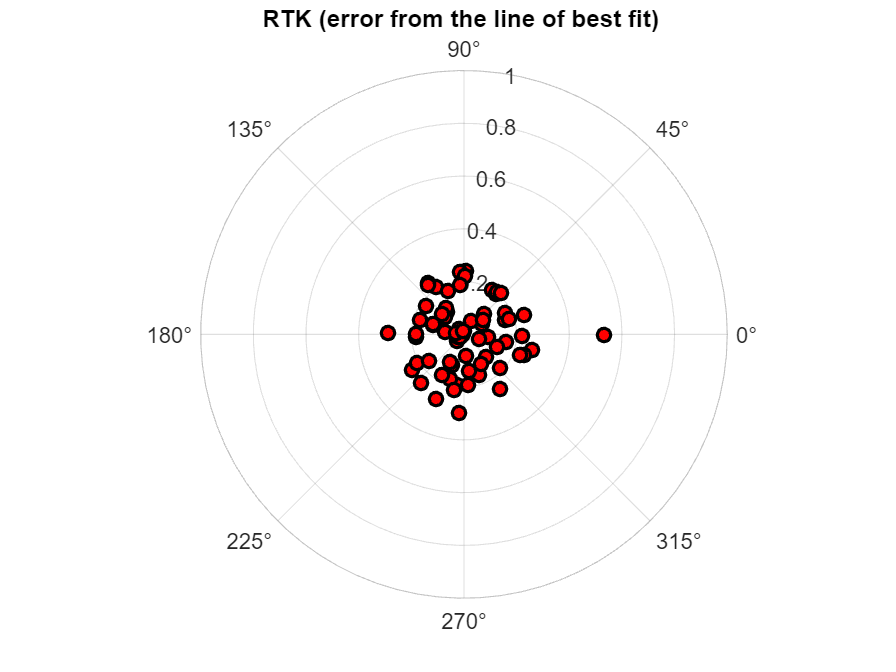

title('RTK (error from the line of best fit) ');

% hold on
 error(ig,og,ug,'b',4)

Quantitative_error = 2.3231

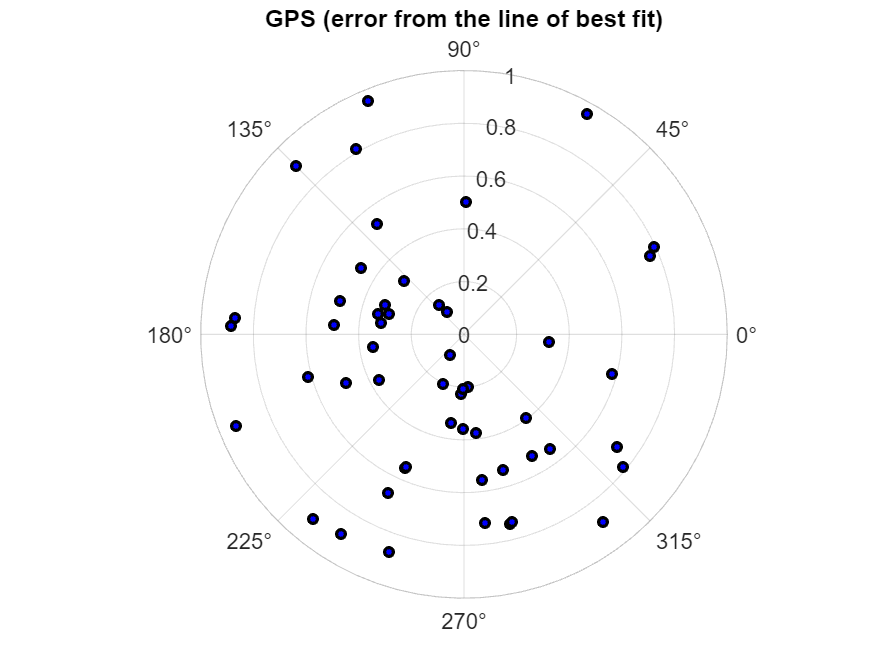



title(' GPS (error from the line of best fit) ');

function[]=error(i,o,UN,c,s)


error=i-o;
e_mean=mean(error(2,:));

Quantitative_error=sqrt(sum((error(2,:)-e_mean).^2)/length(error(2,:)))


angles =UN * 2 * pi; 
magnitudes = error(2,:); 

polarplot(angles, magnitudes, 'o', 'MarkerEdgeColor', 'k', 'MarkerFaceColor', c, 'MarkerSize', s, 'LineWidth', 1.5, 'DisplayName', 'Data Points');







rlim([0, 1]); 
rticks(0:0.2:1); 
thetaticks(0:45:315); 

grid on; 

end












function []= alt(file_path1)

[lat,long,Alt,UtmE,UtmN,delta_time,UE,UN]= extract_bag(file_path1);
d1=delta_time;
a1=Alt

 altitude_(a1,delta_time,'r');
 hold on

function[]= altitude_(Alt,delta_time,c)

t = 1:1:delta_time;

t = linspace(min(t), max(t), length(Alt));


 plot(t, Alt, 'MarkerFaceColor', 'r', 'LineWidth', 1.5);
% scatter(t, Alt, 'Marker', 'o', 'MarkerEdgeColor', 'k', 'MarkerFaceColor', c, 'SizeData', 100, 'LineWidth', 1.5, 'DisplayName', 'Data Points');

xlabel('Time (seconds)');
ylabel('Altitude (meters)');
title('Altitude vs. Time');
legend("Walking")

grid on;

set(gca, 'FontName', 'Arial', 'FontSize', 12);
set(gcf, 'Color', 'w'); 

end
end

function []=scatterplot(UE,UN,c)
scatter(UE, UN);
end




function [lat,long,Alt,UtmE,UtmN,delta_time,UE,UN]= extract_bag(file_path1)
Alt=0;
lat=0;
long=0;
Alt=0;
UtmE=0;
UtmN=0;
delta_time=0;

bag = rosbag(file_path1);
bSel = select(bag,'Topic','/rtk_gnss');
msgStructs = readMessages(bSel,'DataFormat','struct');

len=bSel.NumMessages;
S_time=bSel.StartTime;
E_time=bSel.EndTime;

delta_time=E_time-S_time;
delta_time=round(delta_time)+1;

for i=1:1:len
gps=msgStructs{i};
lat(i)=gps.Latitude;
long(i)=gps.Longitude;
Alt(i)=gps.Altitude;
UtmE(i)=gps.UtmEasting;
UtmN(i)=gps.UtmNorthing;

 UE(i)=UtmE(i)-UtmE(1);
 UN(i)=UtmN(i)-UtmN(1);

Z=gps.Zone;
L=gps.Letter;
H=gps.Hdop;
latD=gps.LatitudeDir;
lonD=gps.LongitudeDir;

end

end






function [lat,long,Alt,UtmE,UtmN,delta_time,UE,UN]= ex_bag(file_path2)
Alt=0;
lat=0;
long=0;
Alt=0;
UtmE=0;
UtmN=0;
delta_time=0;

bag = rosbag(file_path2);
bSel = select(bag,'Topic','/chatter');
msgStructs = readMessages(bSel,'DataFormat','struct');

len=bSel.NumMessages;
S_time=bSel.StartTime;
E_time=bSel.EndTime;

delta_time=E_time-S_time;
delta_time=round(delta_time)+1;

for i=1:1:len
gps=msgStructs{i};
lat(i)=gps.Latitude;
long(i)=gps.Longitude;
Alt(i)=gps.Altitude;
UtmE(i)=gps.UtmEasting;
UtmN(i)=gps.UtmNorthing;

 UE(i)=UtmE(i)-UtmE(1);
 UN(i)=UtmN(i)-UtmN(1);

Z=gps.Zone;
L=gps.Letter;
H=gps.Hdop;
latD=gps.LatitudeDir;
lonD=gps.LongitudeDir;

end

end

















































